# Example: Fitter FSAE TTC

This example interactively guides you through fitting and exporting a magic formula tire model to measurement data acquired from the [FSAE Tire Test Consortium (TTC)](https://www.fsaettc.org/). The process would be similar with data from other sources, but the user would have to write their own parser (input data --> `tydex.Measurement`).

## 1 Import measurement data

FSAE TTC usually tests either

- Drive / Brake (Varying but steady-state slip angle, then slip ratio sweeps)

- Cornering (No slip ratio, but slip angle sweeps)

folder = fileparts(matlab.desktop.editor.getActiveFilename());
fileDriveBrake = fullfile(folder, 'ttc/drivebrake.mat');
fileCornering = fullfile(folder, 'ttc/cornering.mat');
parser = tydex.parsers.FSAETTC_SI_ISO_Mat();
measurementsDriveBrake = parser.run(fileDriveBrake);
measurementsCornering = parser.run(fileCornering);

Downsample data for quicker fitting:

measurements = [measurementsDriveBrake measurementsCornering];
measurementsDownsampled = measurements.downsample(20); % (dt = 0.01s --> 0.2s)

## 2 Fit the tire model

Select modes to fit:

fitmodes = {'Fx0','Fy0','Mz0','Fx','Fy','Mz','Mx'};
% Alternatively, use the enum type:
%   fitmodes = magicformula.FitMode({'Fx0','Fy0'});

Create tire model:

tyre = MagicFormulaTyre();

General model parameters:

tyre.Parameters.NOMPRES.Value = max([measurements.NOMPRES]);
tyre.Parameters.FNOMIN.Value = max([measurements.FNOMIN]);
tyre.Parameters.UNLOADED_RADIUS.Value = 0.2025;

Set other constraints of your choosing:

tyre.Parameters.PCY1.Value = 2;
tyre.Parameters.PCY1.Fixed = true;

Fit model:

options = optimset('fmincon');
options.UseParallel = true;
options.Display = 'none';
options.DiffMinChange = 1E-3;
tyre.fit(measurementsDownsampled, fitmodes, options)

Fitting Fx0...
Finished Fit-Mode: Fx0
Time elapsed 11.2s.

Fitting Fy0...
Finished Fit-Mode: Fy0
Time elapsed 6.3s.

Fitting Mz0...
Finished Fit-Mode: Mz0
Time elapsed 15.7s.

Fitting Fx...
Finished Fit-Mode: Fx
Time elapsed 8.1s.

Fitting Fy...
Finished Fit-Mode: Fy
Time elapsed 6.6s.

Fitting Mx...
Finished Fit-Mode: Mx
Time elapsed 3.0s.

Fitting Mz...
Finished Fit-Mode: Mz
Time elapsed 3.0s.



## 3 Verify model-data fit

If the model fit is not satisfactory, try altering the min/max settings above or the initial values.

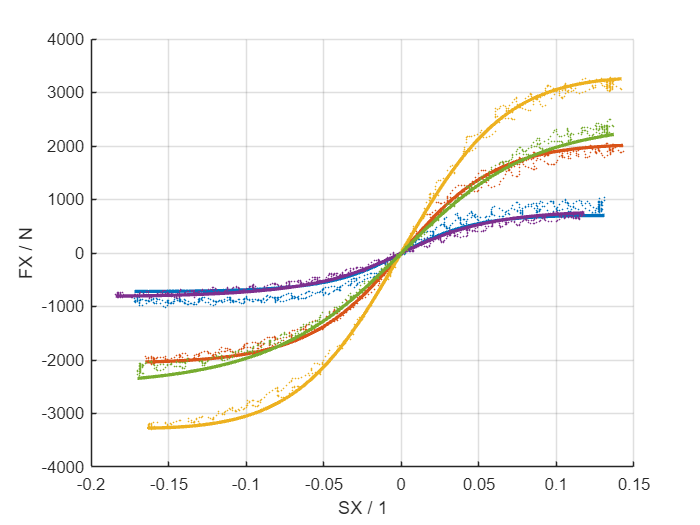

measurements1 = measurementsDriveBrake;
nmeas = numel(measurements1);
nplot = 5;
step = ceil(nmeas/nplot);
indices1 = 1:step:nmeas;

measurements2 = measurementsCornering;
nmeas = numel(measurements2);
nplot = 5;
step = ceil(nmeas/nplot);
indices2 = 1:step:nmeas;

figure(); grid on; hold on
magicformula.plots.compareFxSX(tyre, measurements1(indices1))

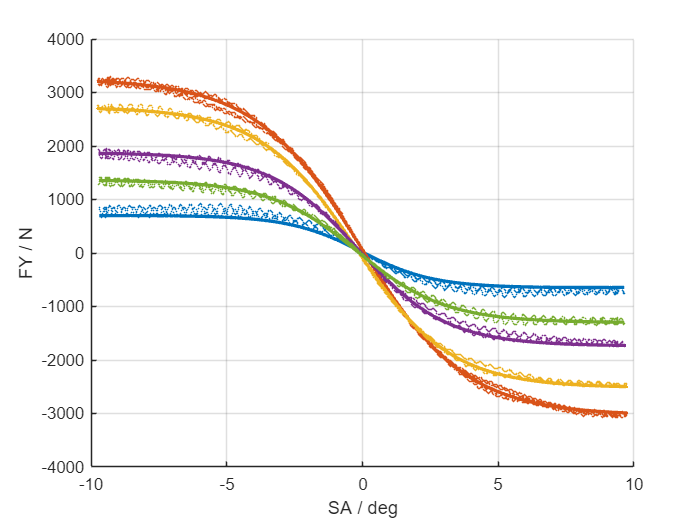

figure(); grid on; hold on
magicformula.plots.compareFySA(tyre, measurements2(indices2))

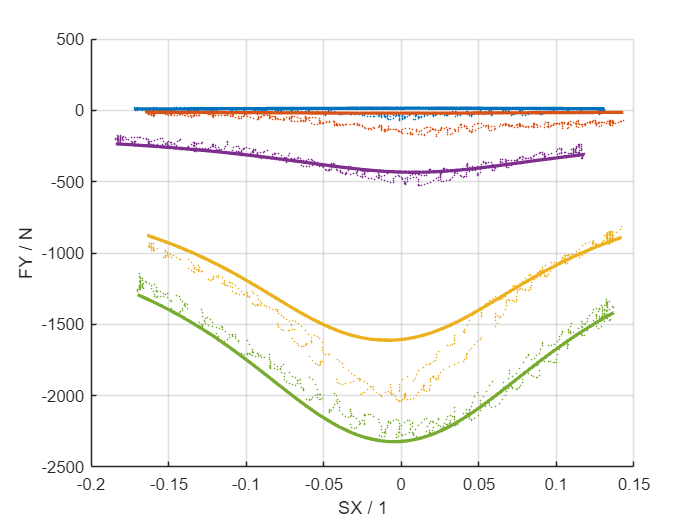

figure(); grid on; hold on
magicformula.plots.compareFySX(tyre, measurements1(indices1))

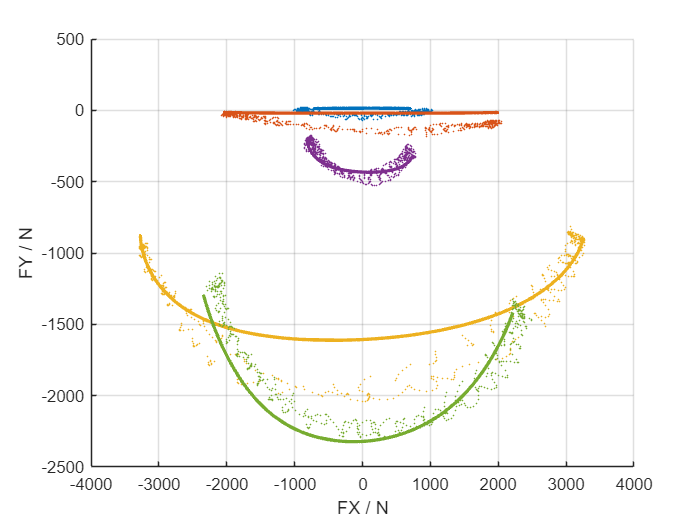

figure(); grid on; hold on
magicformula.plots.compareFxFy(tyre, measurements1(indices1))

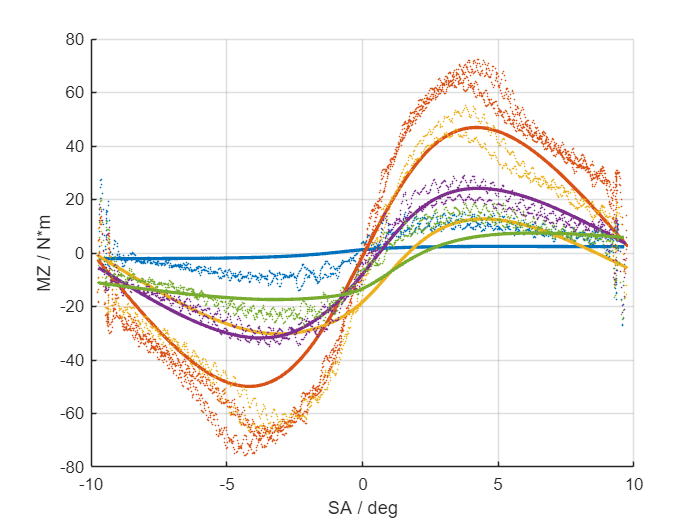

figure(); grid on; hold on
magicformula.plots.compareMzSA(tyre, measurements2(indices2))

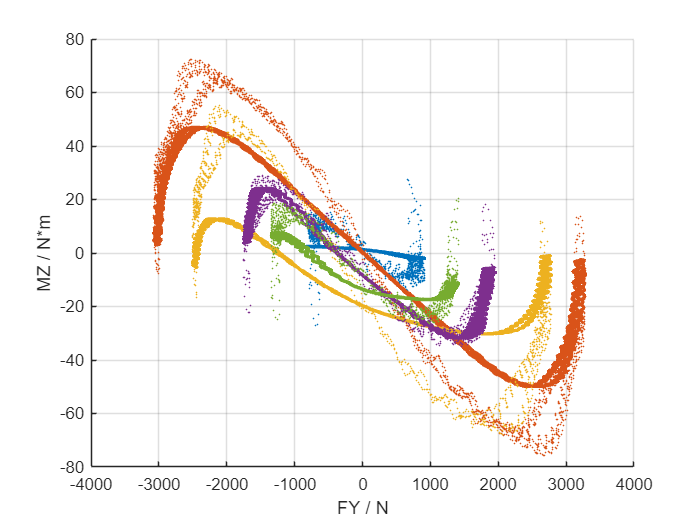

figure(); grid on; hold on
magicformula.plots.compareMzFy(tyre, measurements2(indices2))

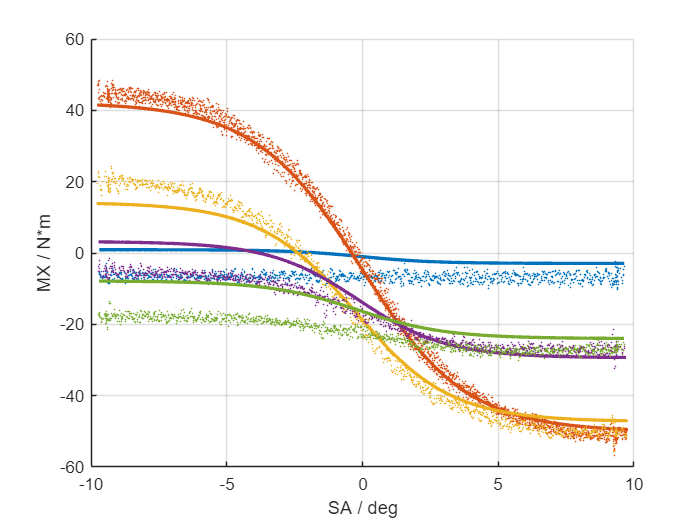

figure(); grid on; hold on
magicformula.plots.compareMxSA(tyre, measurements2(indices2))

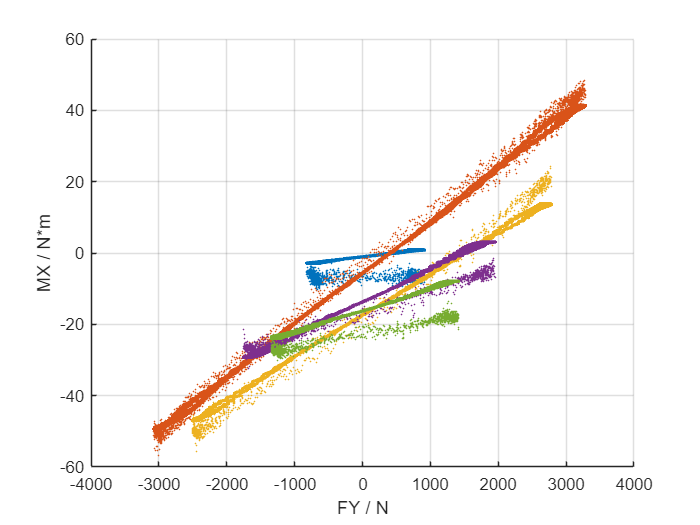

figure(); grid on; hold on
magicformula.plots.compareMxFy(tyre, measurements2(indices2))

## 4 Export fitted model

Export as Tyre Property File (.tir)

file = [tempname() '.tir'];
tyre.saveTIR(file, 'DisplayConsole', false)
winopen(file)

Export as Struct and save to MAT

params = struct(tyre.Parameters);
save('Example.mat', '-struct', 'params')

## 5 Store Fitting Settings

savefile = fullfile(tempdir(), 'test.md');
tyre.Parameters.saveFittingSettings(savefile)
disp(readlines(savefile))

    "| Parameter            | Min                  | Max                  | Fixed                |"
    "| -------------------- | -------------------- | -------------------- | -------------------- |"
    "| PCX1                 | 1.500000E+00         | Inf                  | false                |"
    "| PCY1                 | 1.500000E+00         | 5.000000E+00         | true                 |"
    "| PDX1                 | 1.000000E+00         | 5.000000E+00         | false                |"
    "| PDX2                 | -1.000000E+00        | 0.000000E+00         | false                |"
    "| PDX3                 | 0.000000E+00         | 1.500000E+01         | false                |"
    "| PDXP1                | -Inf                 | Inf                  | false                |"
    "| PDXP2                | -Inf                 | Inf                  | false                |"
    "| PDXP3                | -Inf                 | Inf                  | false                |"
